# Problem 22.10

clear, constants

k =      8.99e+09

e0 =      8.85e-12

e =     1.602e-19

syms q1 x L real positive
assume(x>0)
q2 = -1/4*q1

$$q2 = -\frac{q_{1}}{4}$$

x component of strength of net electric field at x from the just right of the particle 2

Enetx = k*q1/(L+x)^2 + k*q2/x^2

$$Enetx = \frac{8990000000\,q_{1}}{{\left(L+x\right)}^{2}}-\frac{2247500000\,q_{1}}{x^{2}}$$

Enet,x = 0 at x = 0.2 and obrain L from it.

eq = subs(Enetx,x,0.2)==0

$$eq = \frac{8990000000\,q_{1}}{{\left(L+\frac{1}{5}\right)}^{2}}-56187500000\,q_{1}=0$$

Lsol = solve(eq,L)

$$Lsol = \frac{1}{5}$$

Enetx = subs(Enetx,L,Lsol)

$$Enetx = \frac{8990000000\,q_{1}}{{\left(x+\frac{1}{5}\right)}^{2}}-\frac{2247500000\,q_{1}}{x^{2}}$$

(a) Find x for maximum Enet,x

dE = diff(Enetx,x)

$$dE = \frac{4495000000\,q_{1}}{x^{3}}-\frac{17980000000\,q_{1}}{{\left(x+\frac{1}{5}\right)}^{3}}$$

xsol = vpa(solve(dE==0,x))  % answer

$$xsol = 0.34048287678386305361907512358858$$

$\frac{1}{q_1}\frac{dE_{net,x}}{dx}$ plot

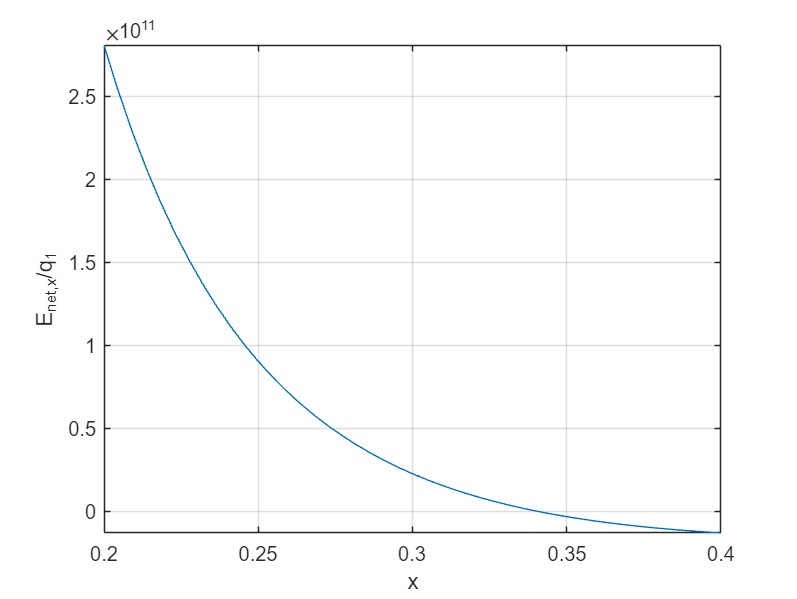

fplot(subs(dE,q1,1)), xlim([0.2 0.4]), grid on
xlabel('x'), ylabel('E_{net,x}/q_1')

(b)What is the value of that maximum when $-q_2 = -3e$ thus $q_1 = 12e$

Enetxmax = vpa(subs(Enetx,[x,q1],[xsol,12*e]),3)    % answer

$$Enetxmax = 2.19e-8$$

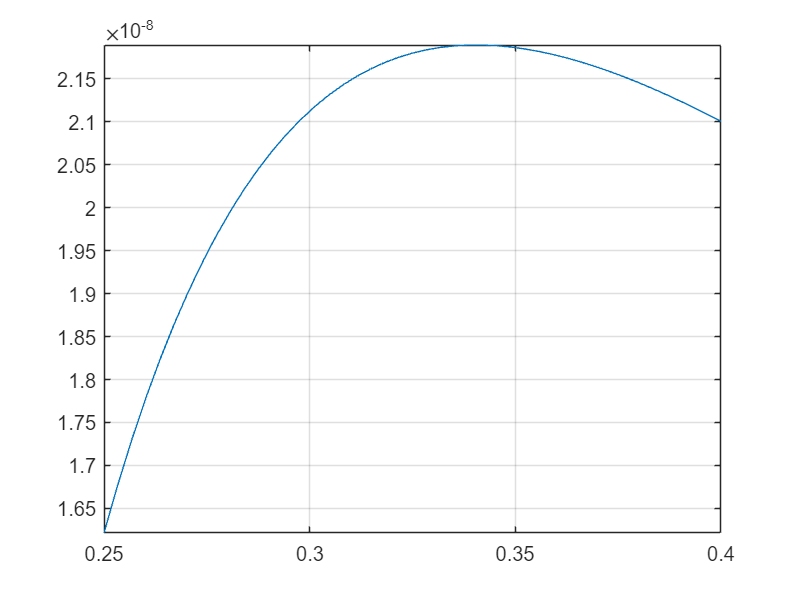

fplot(subs(Enetx,q1,12*e)), xlim([0.25 0.4]), grid on